## Converting the continuous-time model to discrete time

We load the continuous-time transfer function found by identification. We also read the original data for later comparisons. 

clear all;
close all;
load("identifyTransferFunctionContinuousTimeResults.mat");
delta_t= identifyTransferFunctionContinuousTimeResults.delta_t; 
uStep= identifyTransferFunctionContinuousTimeResults.uStep; 
shifted_tData= identifyTransferFunctionContinuousTimeResults.shifted_tData;
shifted_yDeg= identifyTransferFunctionContinuousTimeResults.shifted_yDeg;

We convert the identified transfer function to a state space model. The exact time discretization has been carried out in a maple sheet and we load the matrices Ad, Bd that resulted there. The C and D matrix are the same for the continuous-time state space system and its discrete-time counterpart.

load('mapleToMatlab/Ad.txt'); % provides Ad calculated with maple
load('mapleToMatlab/Bd.txt'); % provides Bd calculated with maple
load('mapleToMatlab/Cd.txt'); 
load('mapleToMatlab/Dd.txt'); 
sysd= ss(Ad, Bd, Cd, Dd, delta_t); 

Let's compare the step response of the discrete-time system to the original simulation data. 

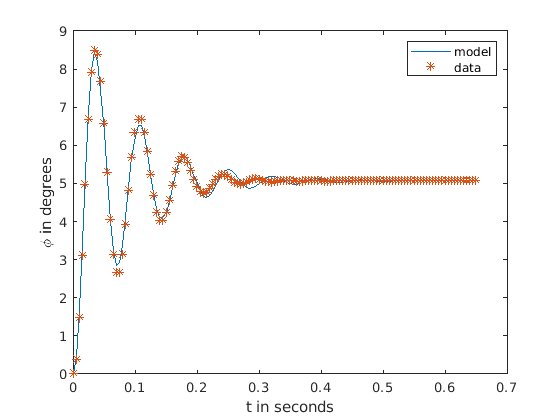

figCounter= 1; 
theStepOptions= stepDataOptions;
theStepOptions.StepAmplitude= uStep; 
[ystep, tstep, xstep]= step(sysd, theStepOptions);
plot(tstep, ystep); 
hold on;
plot(shifted_tData, shifted_yDeg, '*'); 
xlabel('t in seconds');
ylabel('\phi in degrees');
legend('model', 'data'); 
hold off; 

We also plot the angular velocity omega for comparison to the corresponding result for the continuous-time system.

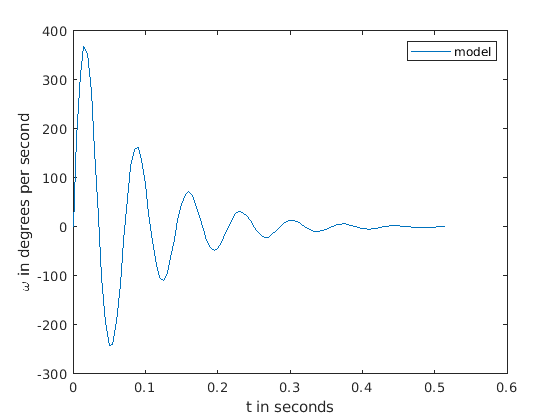

figCounter= figCounter+ 1;
figure(figCounter);
plot(tstep, xstep(:,2));
xlabel('t in seconds');
ylabel('\omega in degrees per second');
legend('model'); 
hold off; 

## Pole placement for state feedback again

Just as for the continuous-time system, we design a state feedback controller by pole placement. For discrete-time systems, however, it is not the open left half plane we need to confine the poles to, but it is the open unit circle. Without going into technical details we here state that the poles for the discrete-time system can be calculated from the continuous-time system poles with the 'inverse bilinear transformation'. 

continuousTimePoles= [-51, -50];
discreteTimePoles= continuousTimePoleToDiscrete(continuousTimePoles, delta_t); 

Kd= place(sysd.A, sysd.B, discreteTimePoles); 

We can now define the closed-loop system with state feedback and check it by plotting a step response. We need to calculate a scaling factor for the reference input again (Bref). 

TODO: Add diagram of closed-loop system with state feedback to explain A-BK. 

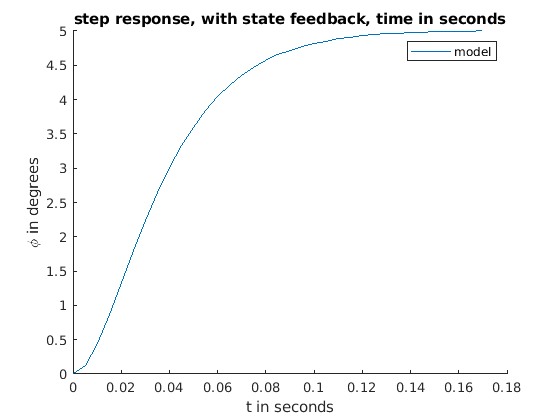

sysDiscreteClosed= ss(sysd.A-sysd.B*Kd, sysd.B, sysd.C, sysd.D, delta_t);

%
% plot closed-loop step response with prefactor
%
figCounter= figCounter+ 1; 
figure(figCounter);
figTitle= "step response, with state feedback, time in seconds";
title(figTitle);
hold on; 
[ySimClosed, tSimClosed]= step(sysDiscreteClosed);
bref= 1/ ySimClosed(end); % input matrix (1x1 matrix here) for scaling the reference input
plot(tSimClosed, ySimClosed*bref*uStep); % instead of multiplying step by Bref we can multiply output, since the system is linear
xlabel('t in seconds');
ylabel('\phi in degrees'); 
legend('model'); 
hold off; 

## State feedback with observer, continuous time, perfect model (again)

Since we cannot measure both states, but only the angular velocity, we have to design an observer in order to be able to use the state feedback. 

Note that our model has the angle as its output. In order to design an observer for the angular velocity, we have to change the output matrix C so as to turn the angular velocity into the output.

observerPolesContTime= [-101 -100];
observerPolesDiscreteTime= continuousTimePoleToDiscrete(observerPolesContTime, delta_t); 
Ldtransposed= place(sysd.A', sysd.C', observerPolesDiscreteTime);
Ld= Ldtransposed'; 

It is convenient to define a system that contains both the simulated system and the observer. This can be done as follows.

Asim = [ sysd.A- sysd.B* Kd             sysd.B* Kd
         zeros(size(sysd.A))    sysd.A- Ld* sysd.C ];

Bsim = [    sysd.B* bref
            zeros(size(sysd.B)) ];

Csim = [ sysd.C, zeros(size(sysd.C)) ];

%simSys= ss(Asim, Bsim, Csim, 0, delta_t);
tSim0= 0:delta_t:0.5; 
numTimeSteps= length(tSim0);
halfNumTimeSteps= floor(numTimeSteps/2);
uSim0= zeros(length(tSim0), 1);
uSim0(halfNumTimeSteps:numTimeSteps) = uStep; 

We need to set the initial conditions and then can run the simulation.

phi0= 20; %deg
omega0= 0; %dps
phiHat0= 0;
omegaHat0= 0;
errPhi0= phi0- phiHat0;
errOmega0= omega0- omegaHat0;
[ySim, xSim]= dlsim(Asim, Bsim, Csim, 0, uSim0, [phi0 omega0 errPhi0 errOmega0]); 

Remember states 3 and 4 are the errors e, where e= x- xhat and xhat are the states of the estimator.

errorSim= xSim(:,3:4);
xhatSim= xSim(:,1:2)- errorSim(:,:);

Plot angles, simulated and observed. 

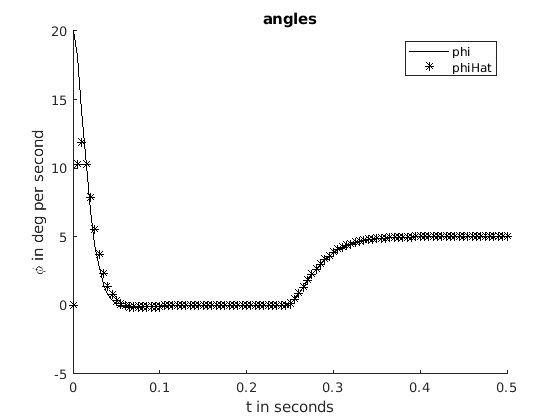

figCounter= figCounter+ 1;
figTitle= "angles";
figure(figCounter);
title(figTitle);
hold on;
plot(tSim0, xSim(:, 1), "Color", "black");
plot(tSim0, xhatSim(:, 1), "*", "Color", "black");
legend('phi', 'phiHat');
xlabel('t in seconds');
ylabel('\phi in deg per second');
hold off; 

Plot angular velocities, simulated and observed.

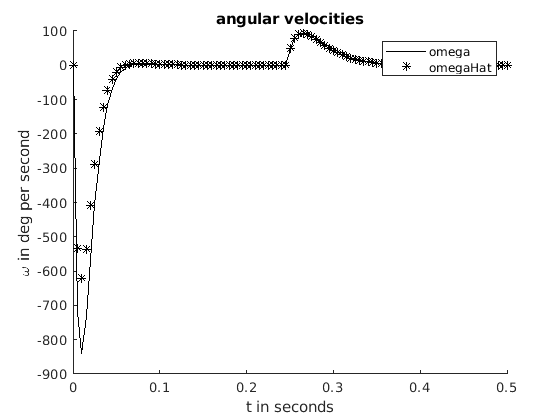

figCounter= figCounter+ 1;
figTitle= "angular velocities";
figure(figCounter);
title(figTitle);
hold on;
plot(tSim0, xSim(:, 2), "Color", "black");
plot(tSim0, xhatSim(:, 2), "*", "Color", "black");
xlabel('t in seconds');
ylabel('\omega in deg per second');
legend('omega', 'omegaHat')
hold off; 

## Switching to output omega.

By replacing C= [1 0]' with Cnew= [0 1] and keeping all other matrices as they are, we obtain a model that has the output omega instead of phi. Since the gyroscope measures omega, this helps to keep the implementation on the microcontroller leaner.

C2= [0 1];

We determine the observer feedback as above.

 
Ldtransposed2= place(sysd.A', C2', observerPolesDiscreteTime); % poles are the same as above
Ld2= Ldtransposed2'; 

We define a simulation system as above. The new system and the system above only differ with respect to the output matrix. 


Asim2 = [ sysd.A- sysd.B* Kd             sysd.B* Kd
         zeros(size(sysd.A))    sysd.A- Ld2* C2 ];

Bsim2 = [    sysd.B* bref
            zeros(size(sysd.B)) ];

Csim2 = [ C2, zeros(size(C2)) ];

Let's look at the same plots again.

[ySim2, xSim2]= dlsim(Asim2, Bsim2, Csim2, 0, uSim0, [phi0 omega0 errPhi0 errOmega0]); 

Remember states 3 and 4 are the errors e, where e= x- xhat and xhat are the states of the estimator.

errorSim2= xSim2(:,3:4);
xhatSim2= xSim2(:,1:2)- errorSim2(:,:);

Plot angles, simulated and observed. 

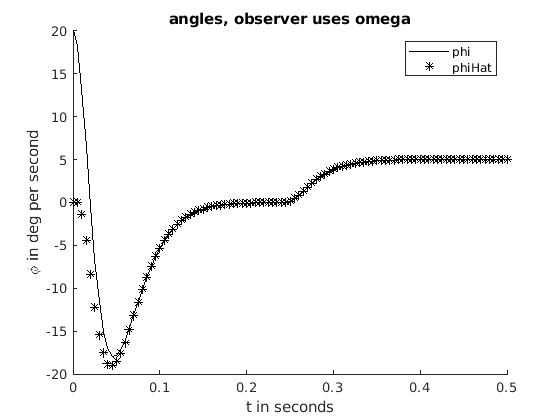

figCounter= figCounter+ 1;
figTitle= "angles, observer uses omega";
figure(figCounter);
title(figTitle);
hold on;
plot(tSim0, xSim2(:, 1), "Color", "black");
plot(tSim0, xhatSim2(:, 1), "*", "Color", "black");
legend('phi', 'phiHat');
xlabel('t in seconds');
ylabel('\phi in deg per second');
hold off; 

Plot angular velocities, simulated and observed. 

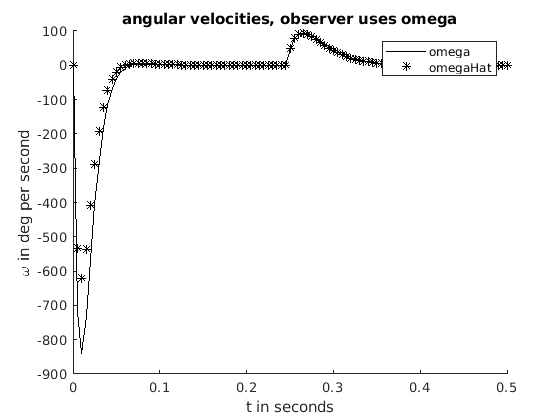

figCounter= figCounter+ 1;
figTitle= "angular velocities, observer uses omega";
figure(figCounter);
title(figTitle);
hold on;
plot(tSim0, xSim(:, 2), "Color", "black");
plot(tSim0, xhatSim(:, 2), "*", "Color", "black");
xlabel('t in seconds');
ylabel('\omega in deg per second');
legend('omega', 'omegaHat')
hold off;

Store system, controller and observer matrices as simple c-code for use with the microcontroller. Store the same data also in a matlab file for easier reuse. 

fileName= "matlabToC/matricesForOutputPhi/matricesForOutputPhi.c";
fh= fopen(fileName, 'w');
printToC(Ad, 'Ad', fh);
printToC(Bd, 'Bd', fh);
printToC(Cd, 'Cd', fh);
printToC(Kd, 'Kd', fh);
printToC(Ld, 'Ld', fh);
printToC(bref, 'bref', fh); 

matricesForOutputPhi.Ad= Ad;
matricesForOutputPhi.Bd= Bd;
matricesForOutputPhi.Cd= Cd;
matricesForOutputPhi.Dd= Dd;
matricesForOutputPhi.Kd= Kd;
matricesForOutputPhi.Ld= Ld;
matricesForOutputPhi.bref= bref;
save('matlabToC/matricesForOutputPhi/matricesForOutputPhi.mat', 'matricesForOutputPhi');

Store also for the case of output omega.

fileName= "matlabToC/matricesForOutputOmega/matricesForOutputOmega.c";
fh= fopen(fileName, 'w');
printToC(Ad, 'Ad', fh);
printToC(Bd, 'Bd', fh);
printToC(C2, 'Cd', fh);
printToC(Kd, 'Kd', fh);
printToC(Ld2, 'Ld', fh);
printToC(bref, 'bref', fh); 

matricesForOutputOmega.Ad= Ad;
matricesForOutputOmega.Bd= Bd;
matricesForOutputOmega.Cd= C2;
matricesForOutputOmega.Kd= Kd;
matricesForOutputOmega.Ld= Ld2;
matricesForOutputOmega.bref= bref;
save('matlabToC/matricesForOutputOmega/matricesForOutputOmega.mat', 'matricesForOutputOmega');

## Auxiliary functions

Functions defined here at the end of the live-script can be called in the live-script above.

function z= continuousTimePoleToDiscrete(s, Ts)
%CONTINUOUSTIMEPOLETODISCRETE Applies inverse bilinear transformation to s. 
% Converts pole s (or any other point in C) to discrete time pole with
% bilinear transformation, where Ts is the sampling time.

% if more than one pole is given in s, loop over all of them
numPoles= length(s);
if numPoles==1
    z= (2+s*Ts)/(2-s*Ts);
else
    z= zeros(1, numPoles); % allocate to avoid dynamic allocation
    for k= 1:numPoles 
        z(k)= continuousTimePoleToDiscrete(s(k), Ts);
    end
end

end